clear all;
load sequence_heart2_train.mat;

max(sequence)

ans = 9

min(sequence)

ans = 3

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |        4.94% |       15.51% |       2.1551 |       2.0587 |          0.0010 |
|      50 |          50 |       00:00:07 |       50.56% |       51.01% |       1.3771 |       1.3632 |          0.0010 |
|     100 |         100 |       00:00:09 |       66.40% |       66.40% |       0.9165 |       0.9109 |          0.0010 |
|     150 |         150 |       00:00:10 |       73.37% |       74.61% |       0.7009 |       0.6903 |          0.0010 |
|     20

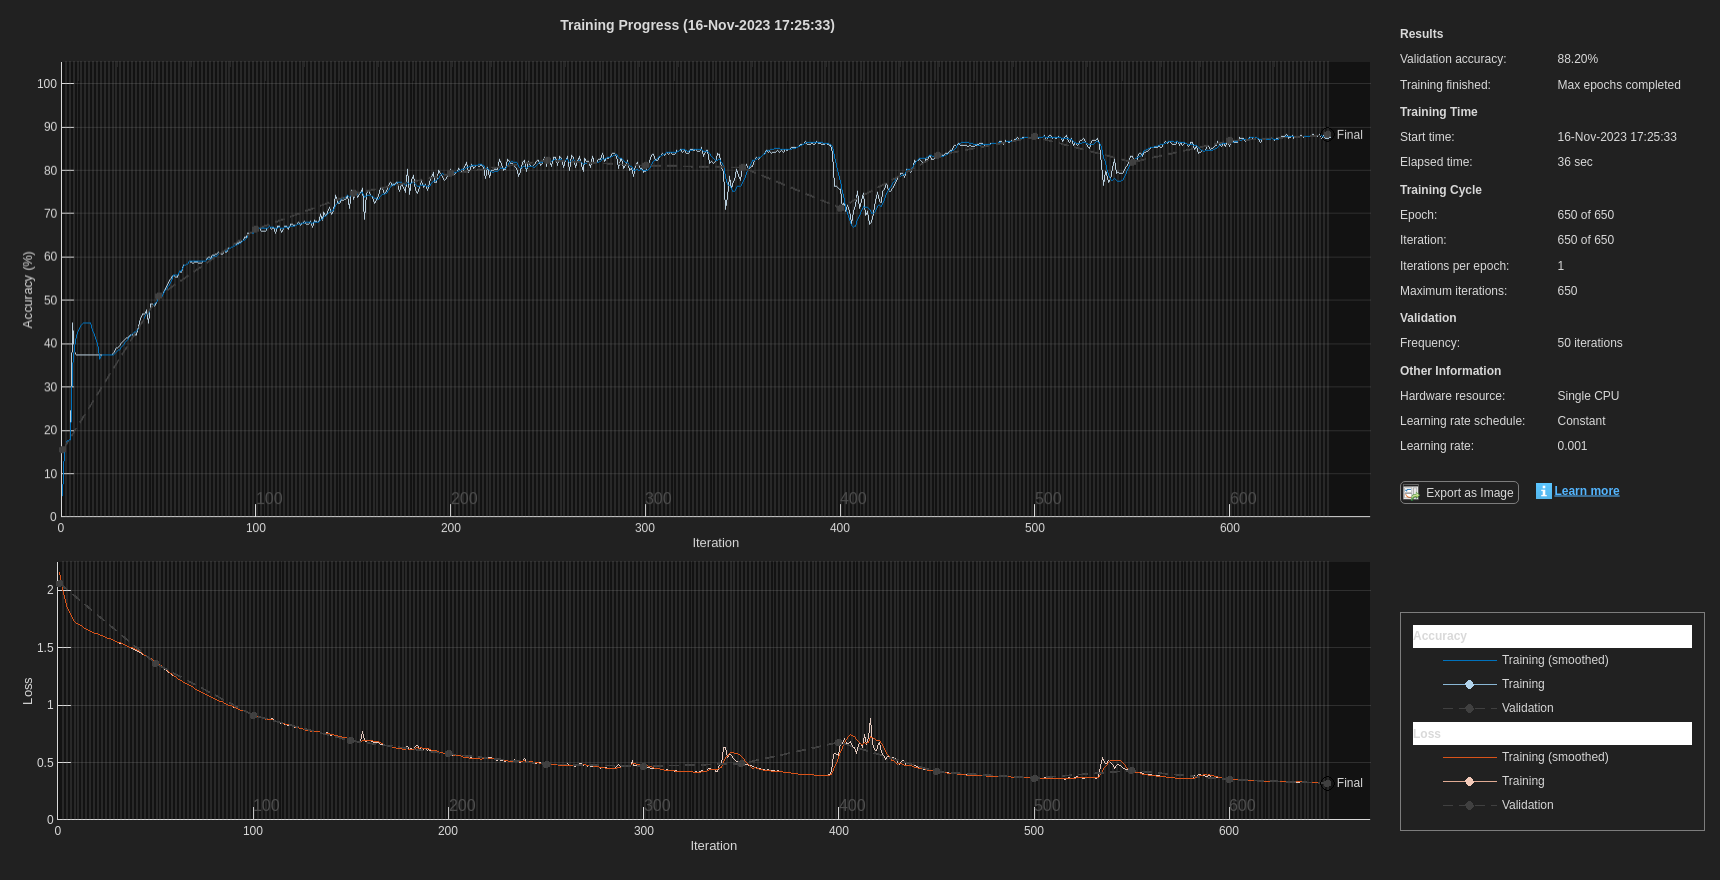


time_series_data = sequence;

% Assuming you have a 1D time series data named 'time_series_data'
sequence_length = 10;  % Length of input sequences
num_samples = length(time_series_data) - sequence_length;

% Create sequences
X = zeros(sequence_length, num_samples);
y = zeros(1, num_samples);

for i = 1:num_samples
    X(:, i) = time_series_data(i:i+sequence_length-1);
    y(i) = time_series_data(i+sequence_length);
end

% Reshape the input data for LSTM
X = permute(X, [1, 2, 3]);  % [10, num_samples, 1]

% Build the modified LSTM model with 9 output neurons
numUnits = 50;
numClasses = 7;  % Number of output classes

layers = [
    sequenceInputLayer(sequence_length)
    lstmLayer(numUnits, 'OutputMode','sequence')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
];

% Training options (modify as needed)
options = trainingOptions('adam', ...
    'MaxEpochs', 650, ...
    'MiniBatchSize', 32, ...
    'ValidationData', {X, categorical(y)}, ...  % Use categorical labels for classification
    'Plots', 'training-progress');

% Train the modified LSTM model
net = trainNetwork(X, categorical(y), layers, options);

net=resetState(net);

sequenceLength = initializeSymbolMachine('sequence_heart2_test.mat',0);

Initialized Symbol Machine for sequence_heart2_test.mat, which contains 900 symbols.
Use symbolMachine.m to make forecasts.



probs = [1/9 1/9 1/9 1/9 1/9 1/9 1/9 1/9 1/9];
%%input = zeros([10 sequenceLength-10]);
for ii = 1:10
    [symbol,penalty] = symbolMachine(probs);
    input(ii, 1) = symbol;
end
predictions = zeros([9 sequenceLength]);
for ii = 11:sequenceLength
    net=resetState(net);
    predictions = predict(net, input);
    probs = predictions(:, ii-10);
    %%disp(predictions);
    probs(8) = 0;
    probs(9) = 0;
    probs = circshift(probs, 2);
    [symbol, penalty] = symbolMachine(probs);
    input(:, ii-9) = circshift(input(:, ii-10), -1);
    input(10, ii-9) = symbol;
end
reportSymbolMachine;

SYMBOL MACHINE REPORT (EMAIL TO PROF WAKIN FOR LEADERBOARD)
Processed 900 out of 900 symbols in sequence_heart2_test.mat.
Total penalty: 1962.985 bits (2.1811 bits per symbol).
     5155 probabilities forecasted between 0.0000 (Inf bits) and 0.0039 (8 bits); actual occurrence rate 0.0037.
      290 probabilities forecasted between 0.0039 (8 bits) and 0.0078 (7 bits); actual occurrence rate 0.0621.
      371 probabilities forecasted between 0.0078 (7 bits) and 0.0156 (6 bits); actual occurrence rate 0.1267.
      288 probabilities forecasted between 0.0156 (6 bits) and 0.0312 (5 bits); actual occurrence rate 0.1562.
      255 probabilities forecasted between 0.0312 (5 bits) and 0.0625 (4 bits); actual occurrence rate 0.2549.
      288 probabilities forecasted between 0.0625 (4 bits) and 0.1250 (3 bits); actual occurrence rate 0.2604.
      283 probabilities forecasted between 0.1250 (3 bits) and 0.2500 (2 bits); actual occurrence rate 0.3498.
      317 probabilities forecasted between 0